# Neuronas selectivas

Sean $L$ puntos aleatorios $X \sim \mathcal{U} [-1, 1]^{n_s}$, y $m_s$ neuronas, de forma que $m_s >> L$. Queremos conseguir que las neuronas sean selectivas. Esto significa que cada una se activará con un estímulo, y sólo uno. Diremos que no será selectiva si se activa con más de un estímulo y estará inactiva cuando no se active con ninguno.

Comencemos de momento definiendo los parámetros y los estímulos.

L = 50;

ms = 100;
ns = 30;
mc = 100;
nc = ms;

X = generateStimuli(L, ns, -1, 1);
% normalizado
X = sqrt(3 / ns) * X;

Las reglas de aprendizaje que vamos a usar van a ser las siguientes:

- La función de activación de cada neurona será una relu $H(u) = \max\{0, u\}$.

- El umbral de activación será $\theta$ y $v_j = w_j x_i$ será el potencial de membrana para la neurona $j$, dado el estímulo $x_i$, y siendo $w_j$ el vector de pesos de la neurona $j$. Por tanto, la salida de la neurona $j$ ante el estímulo $x_i$ será $H(v_j - \theta)$.

- Para seleccionar el estímulo $x_i$ en el momento $t$, se va a simplificar eligiendo rotativamente $\sqrt{\frac{3}{n_s}} x_k$, donde $k$ es el entero siguiente al módulo de la división entre$\lfloor t \rfloor$ y $L$. El coeficiente que acompaña a la $x$ proviene de la distribución de  $v_j$.

- La regla de actualización es una ecuación diferencial $\dot{w_j} = \alpha y_j (\beta^2 x_i - v_j w_j)$. Aquí $\alpha > 0$ es el ratio de aprendizaje y $\beta > 0$ es un parámetro que se calcula en función de la probabilidad $p_{sl}$ que se quiera de que una neurona que se ha activado ante un estímulo siga haciéndolo en el futuro y de la dimensión $n_s$. Esta ecuación diferencial la podemos resolver numéricamente.

p = .95;

theta = 1;
delta = sqrt(1 - (2 * norminv(p)) / (sqrt(5) * ns));

alpha = 5;
beta = theta / delta;

sext = @(t) X(mod(t, L) + 1, :);
H = @(u) max(0, u);

Pasamos, por fin, a entrenar la red neuronal.

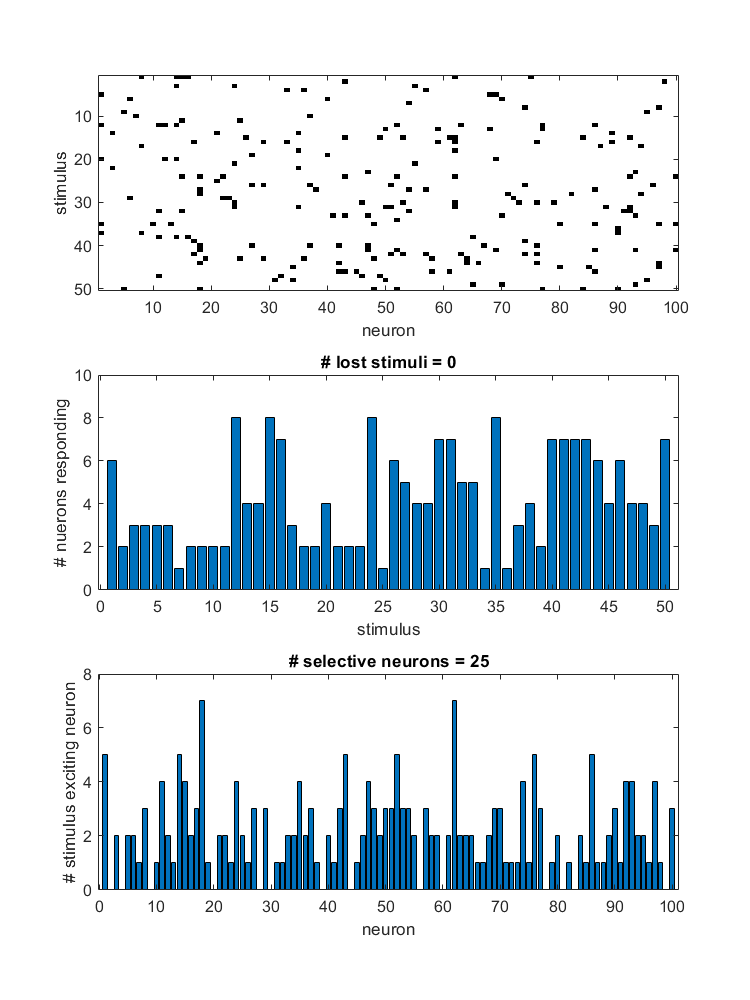

T = 3 * L;
h = .005;
steps = T / h;

Ws = 2 * rand(ms, ns) - 1;
Wc = 2 * rand(mc, nc) - 1;

% Estado inicial
Y = H(Ws * X' - theta) > 0;

figure('color', 'w', 'position', [100 100 600 800]);
plotResults(Y);

% Entrenamiento
for k = 1:steps
    t = floor((k - 1) * h);
    x = sext(t);
    v = Ws * x';
    y = H(v - theta);
    Ws = Ws + h * alpha * y.* (beta^2 * x - v.* Ws);
end

Resultados.

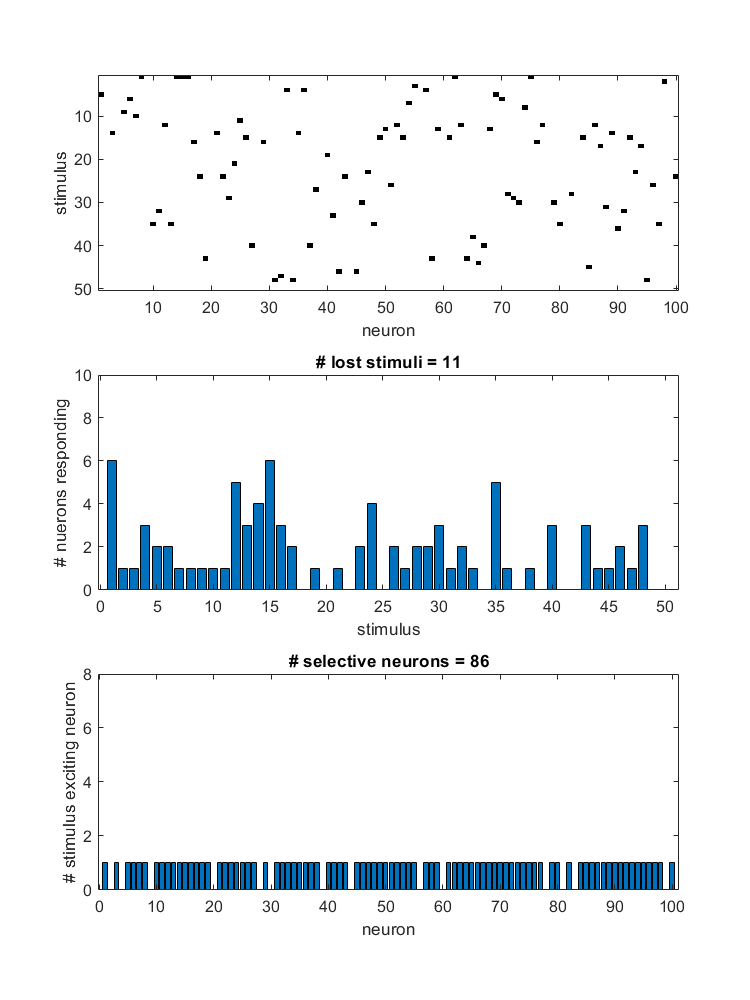

Y = H(Ws * X' - theta) > 0;

plotResults(Y);

function X = generateStimuli(N, n, min, max)
    X = min + rand(N, n) * (max - min);
end